% BVP 
% -ddu/dxx = exp(-cos(x))
% x in [-pi, pi] with periodic BCs

% parameters
M = pi; 
N = 1000; 
h = 2*M/(N); 
xGrid = -M+h : h: M;

phi = @(x) exp(-cos(x));
f = @(x) cos(x);

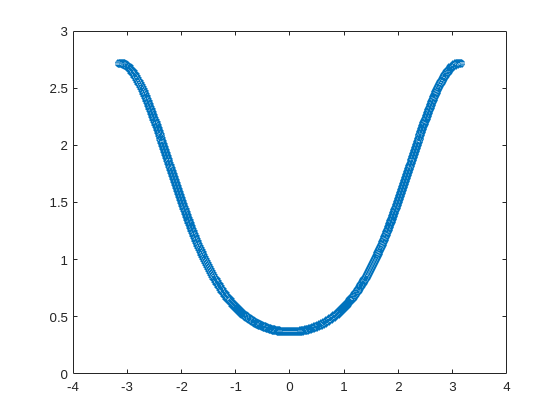

figure();

plot(xGrid, phi(xGrid), 'o');

% first order derivative
col = [0 -1 zeros(1,N-2)]'; 
row = [0 1 zeros(1,N-2)];
SD = toeplitz(col,row);
SD(1,N+1) = -1;
SD(N+1,1) = 1; % modifications to make differencing periodic
SD = SD/(2*h);

 % for second order derivative
col = [-2 1 zeros(1,N-2)]';
row = [-2 1 zeros(1,N-2)];
TD = toeplitz(col,row);
TD(1,N+1) = 1;
TD(N+1,1) = 1; % modifications to make differencing periodic
TD = TD/h/h;

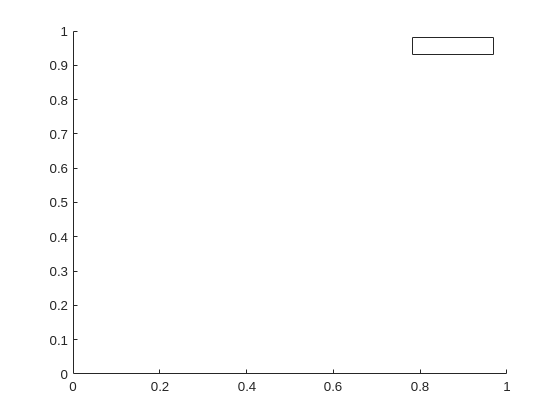

figure();
legend('Location','best');

hold on;

plot(xGrid, TD\phi(xGrid), 'o', ...
    'DisplayName', "TD");

Error using  \ 
Matrix dimensions must agree.

%plot(xGrid, SD*SD*phi(xGrid)', 'x', ...
%    'DisplayName', "SD*SD");
hold off;

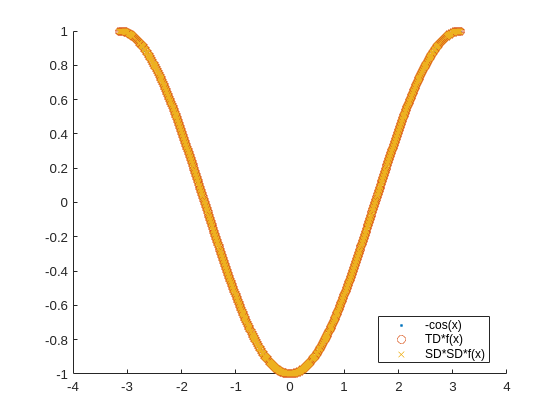

figure();
legend('Location','best');

hold on;
plot(xGrid, -cos(xGrid), '.', 'DisplayName', "-cos(x)");
plot(xGrid, TD*f(xGrid)', 'o', 'DisplayName', "TD*f(x)");
plot(xGrid, SD*SD*f(xGrid)', 'x', 'DisplayName', "SD*SD*f(x)");
hold off;